clear all
ports = serialportlist;
pb = PyBench(ports(end));

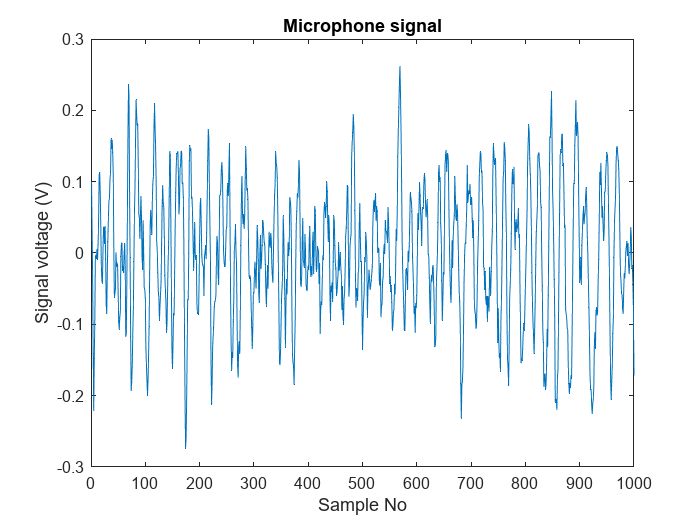


fs = 8000; 
pb = pb.set_samp_freq(fs);

N = 1000;
samples = pb.get_mic(N);
data = samples - mean(samples);

figure(1);
clf
plot(data);
xlabel('Sample No');
ylabel('Signal voltage (V)');
title('Microphone signal');

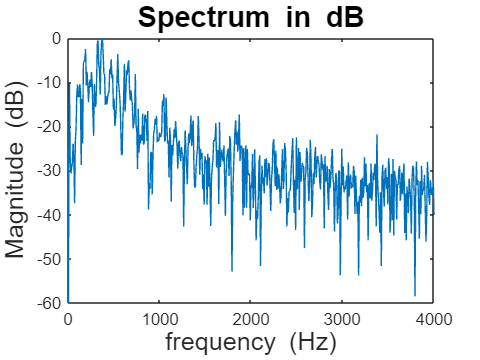


figure(2);
plot_spec_dB(data,fs);

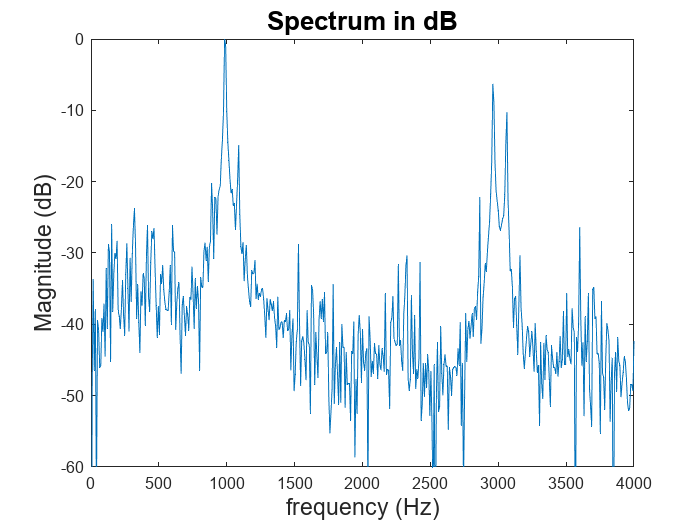


while true
    samples = pb.get_mic(N);
    data = samples - mean(samples);
    figure(2)
    clf;
    plot_spec_dB(data, fs);
end